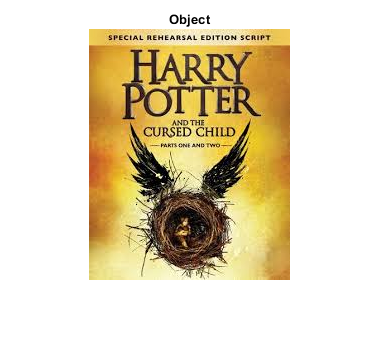

%% Detecting an Object in the Image of a Cluttered Scene Demo
% Copyright 2014 The MathWorks, Inc.
%% Clear workspace 
close all;
clear all;
clc;
%% Read Images
I1 = imread('1_Book.JPG');
figure;
imshow(I1);
title('Object');

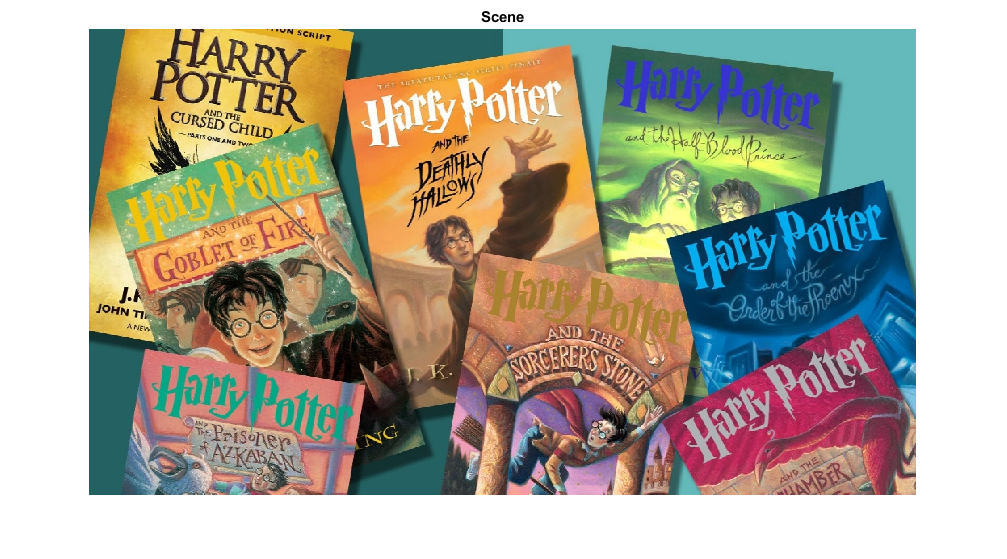

I2 = imread('Cluster_Books.JPG');    
figure;
imshow(I2);
title('Scene');

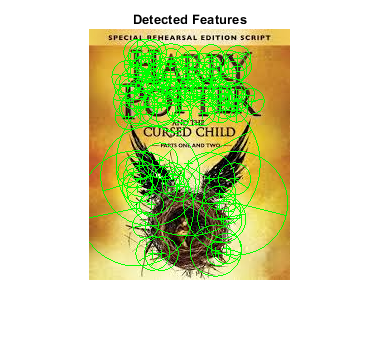

%% Detect SURF Features
points1 = detectSURFFeatures(rgb2gray(I1));
points2 = detectSURFFeatures(rgb2gray(I2));
%% Extract Features
[feats1,validpts1] = extractFeatures(rgb2gray(I1),points1);
[feats2,validpts2] = extractFeatures(rgb2gray(I2),points2);
%% Display 100 strongest features from I1
figure;
imshow(I1);
hold on;
plot(validpts1.selectStrongest(100),'showOrientation',true);
title('Detected Features');

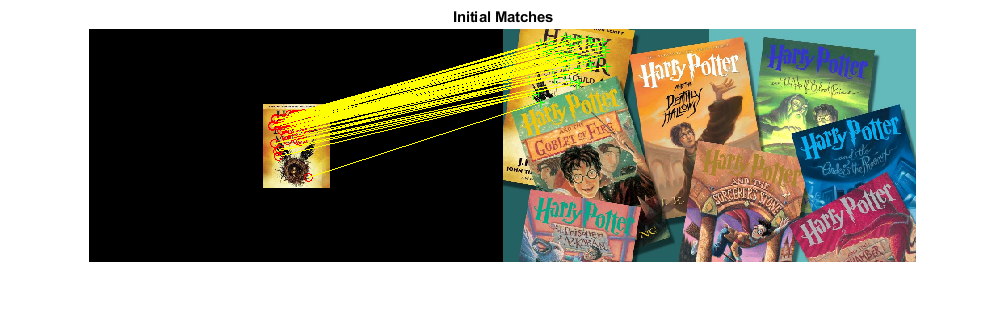

%% Match Features
index_pairs = matchFeatures(feats1, feats2,...
                             'Prenormalized', true);
matched_pts1 = validpts1(index_pairs(:, 1));
matched_pts2 = validpts2(index_pairs(:, 2));
figure; 
showMatchedFeatures(I1,I2,matched_pts1,matched_pts2,'montage');
title('Initial Matches');

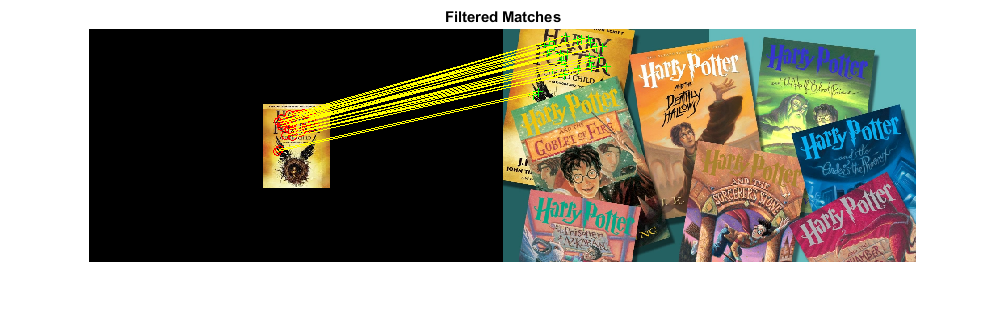

% Define location of object in image
boxPolygon = [1, 1;...                           % top-left
             size(I1, 2), 1;...                  % top-right
             size(I1, 2), size(I1, 1);...        % bottom-right
             1, size(I1, 1);...                  % bottom-left
             1, 1];                               % top-left again to close the polygon
%% Remove outliers while estimating geometric transform using RANSAC
[tform, inlieroints1, inlierPoints2] = estimateGeometricTransform(matched_pts1,matched_pts2,'affine');
figure; 
showMatchedFeatures(I1,I2,inlieroints1,inlierPoints2,'montage');
title('Filtered Matches');

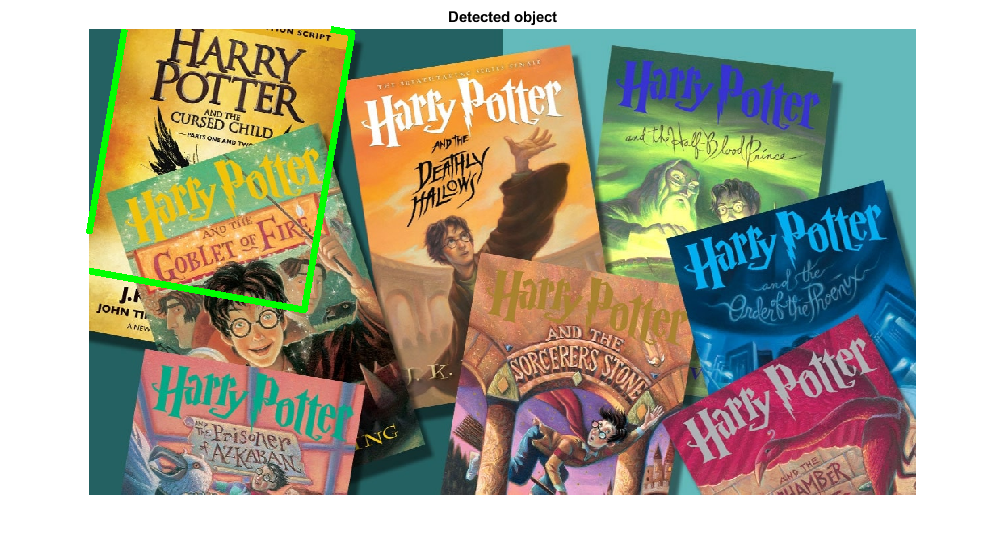

     
%% Use estimated transfor to locate object 
newBoxPolygon = transformPointsForward(tform, boxPolygon);
%% Overlat the detected location of object in Image I2
figure; 
imshow(I2);
hold on;
line(newBoxPolygon(:, 1), newBoxPolygon(:, 2), 'Color', 'g','LineWidth',5);
title('Detected object');